# **Numerical Integration (Trapezoids)**

Function

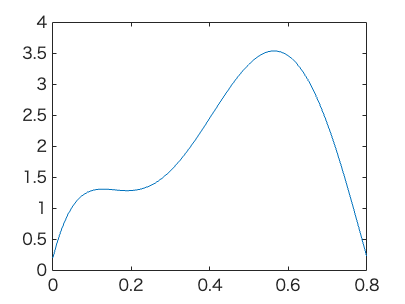

f=@(x) 400.*x.^5 - 900.*x.^4 + 675.*x.^3 - 200.*x.^2 + 25.*x + 0.2;

xx = 0 : 0.01 : 0.8;
yy = f(xx);

plot(xx, yy, '-')

To integrate function from 0 to 0.8 *(doing analytical integration)*

format short
a = 0;
b = 0.8;
p = [400 -900 675 -200 25 0.2];
q = polyint(p) % integrate polynomial equation (gives us the EXACT integration)
Itrue = diff(polyval(q, [a, b])) % for finding relative error
Itrue_integral = integral(f, a, b)

Plot original function along with trapezoidal rule ns = 1

ns = 1

ns = 1

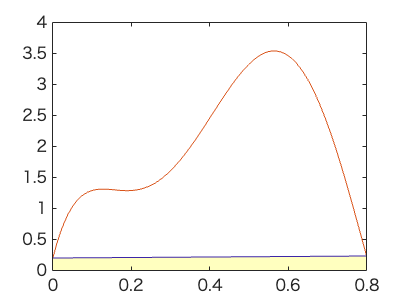

x = linspace(0, 0.8, ns+1);
y = f(x);

figure
area(x, y, 'FaceColor','y','FaceAlpha',0.25,'EdgeColor','flat','LineStyle','-')
hold on
plot(xx, yy, '-')

Plot original function along with trapezoidal rule ns = 2

ns = 2

ns = 2

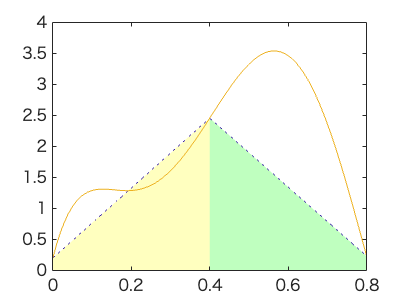

x = linspace(0, 0.8, ns+1);
y = f(x);

figure
colors = ['g', 'y'];

for i = 1:ns
    area(x(i:i+1), y(i:i+1), 'FaceColor',colors(mod(i,2)+1),'FaceAlpha',0.25,'EdgeColor','flat','LineStyle',':')
    hold on
end
plot(xx, yy, '-')

Plot original function along with trapezoidal rule ns = 3

ns = 3

ns = 3

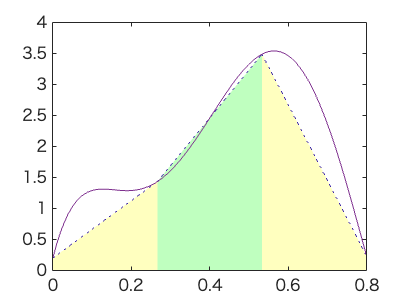

x = linspace(0, 0.8, ns+1);
y = f(x);

figure
colors = ['g', 'y'];

for i = 1:ns
    area(x(i:i+1), y(i:i+1), 'FaceColor',colors(mod(i,2)+1),'FaceAlpha',0.25,'EdgeColor','flat','LineStyle',':')
    hold on
end
plot(xx, yy, '-')

Plot original function along with trapezoidal rule ns from 1 until 10

ns = 10

ns = 10

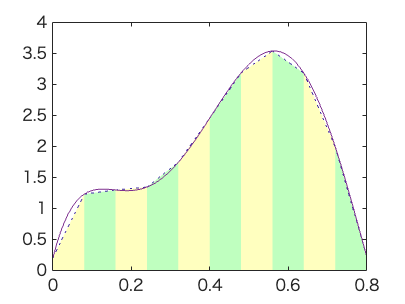

x = linspace(0, 0.8, ns+1);
y = f(x);

figure
colors = ['g', 'y'];

for i = 1:ns
    area(x(i:i+1), y(i:i+1), 'FaceColor',colors(mod(i,2)+1),'FaceAlpha',0.25,'EdgeColor','flat','LineStyle',':')
    hold on
end
plot(xx, yy, '-')

Plot original function along with trapezoidal rule ns from 1 until 20

ns = 20

ns = 20

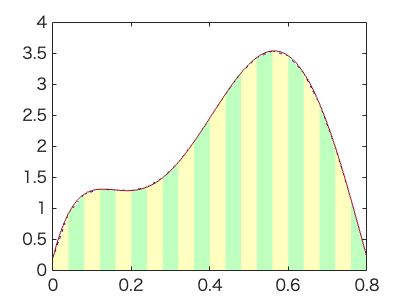

x = linspace(0, 0.8, ns+1);
y = f(x);

figure
colors = ['g', 'y'];

for i = 1:ns
    area(x(i:i+1), y(i:i+1), 'FaceColor',colors(mod(i,2)+1),'FaceAlpha',0.25,'EdgeColor','flat','LineStyle',':')
    hold on
end
plot(xx, yy, '-')